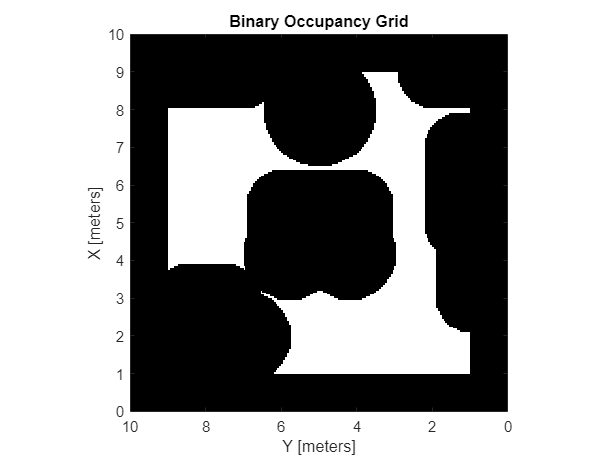

colobj = roomspec();

resolution = 20;
binary_map = colobj2binary_map(colobj, resolution);

binary_map_inflated = binaryOccupancyMap(binary_map);

inflate(binary_map_inflated, 0.9)
show(binary_map_inflated)
view(-90,90);


%p_start = rand_pt_in_map(binary_map_inflated);
%p_end = rand_pt_in_map(binary_map_inflated);
p_start = [2 1.5]

p_start =     2.0000    1.5000


p_end = [8 8]

p_end =      8     8


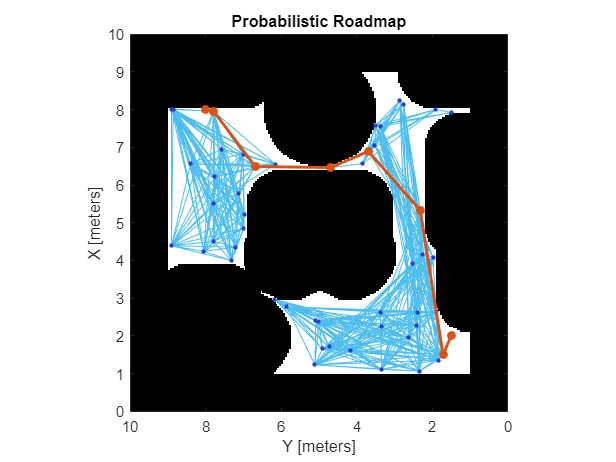



prm = mobileRobotPRM(binary_map_inflated);
xy = findpath(prm,p_start,p_end);

show(prm)
view(-90,90);

% generate trajectory for offset point
dists = [0 cumsum(vecnorm(diff(xy)'))]

dists =          0    0.5440    4.4211    6.5045    7.5939    9.5920   11.4216   11.6354



[lambda,~,~,~,~] = trapveltraj([0 dists(end)],400)

lambda =          0    0.0002    0.0007    0.0015    0.0026    0.0041    0.0059    0.0081    0.0105    0.0133    0.0164    0.0199    0.0237    0.0278    0.0322    0.0370    0.0421    0.0475    0.0533    0.0594    0.0658    0.0725    0.0796    0.0870    0.0947    0.1028    0.1112    0.1199    0.1289    0.1383    0.1480    0.1580    0.1684    0.1791    0.1901    0.2014    0.2131    0.2251    0.2375    0.2501    0.2631    0.2764    0.2901    0.3041    0.3184    0.3330    0.3480    0.3633    0.3789    0.3948


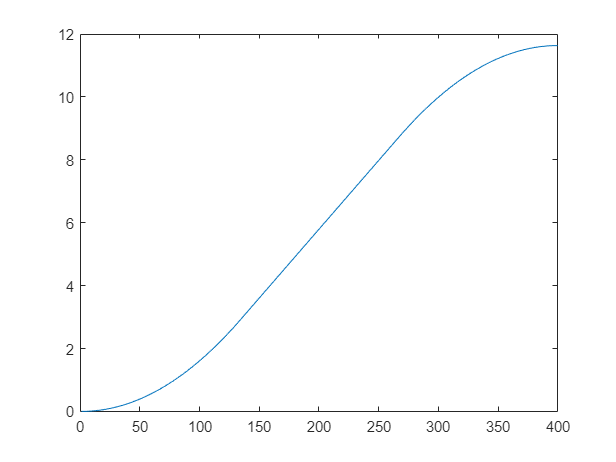

plot(lambda)



traj = interp1(dists,xy,lambda);
traj=traj';
traj = smoothdata(traj, 2, "movmean", 40);

dists2 = [0 cumsum(vecnorm(diff(traj')'))]

dists2 =          0    0.0022    0.0044    0.0068    0.0093    0.0119    0.0146    0.0175    0.0204    0.0234    0.0266    0.0298    0.0332    0.0367    0.0403    0.0440    0.0478    0.0517    0.0557    0.0599    0.0641    0.0707    0.0776    0.0849    0.0924    0.1003    0.1085    0.1171    0.1260    0.1352    0.1447    0.1546    0.1648    0.1753    0.1862    0.1973    0.2088    0.2207    0.2329    0.2449    0.2564    0.2674    0.2778    0.2876    0.2968    0.3055    0.3135    0.3211    0.3280    0.3345


[lambda2,~,~,~,~] = trapveltraj([0 dists2(end)],400)

lambda2 =          0    0.0002    0.0006    0.0014    0.0025    0.0038    0.0055    0.0075    0.0098    0.0125    0.0154    0.0186    0.0221    0.0260    0.0301    0.0346    0.0394    0.0445    0.0498    0.0555    0.0615    0.0678    0.0744    0.0814    0.0886    0.0961    0.1040    0.1121    0.1206    0.1294    0.1384    0.1478    0.1575    0.1675    0.1778    0.1884    0.1993    0.2106    0.2221    0.2340    0.2461    0.2586    0.2713    0.2844    0.2978    0.3115    0.3255    0.3398    0.3544    0.3693


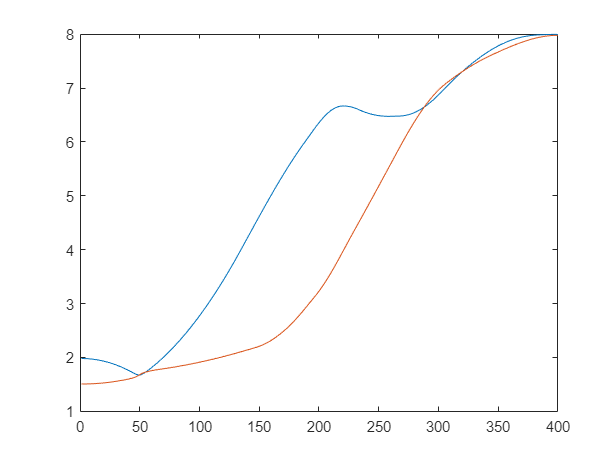

traj = interp1(dists2,traj',lambda2)';


plot(traj')

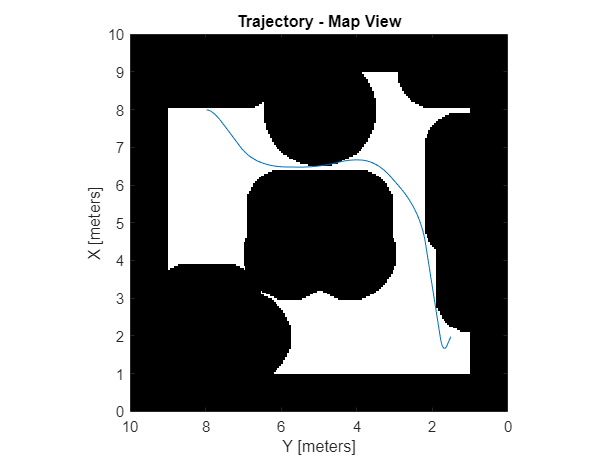

show(binary_map_inflated); hold on
plot(traj(1,:),traj(2,:)); hold off
view(-90,90);
title("Trajectory - Map View")

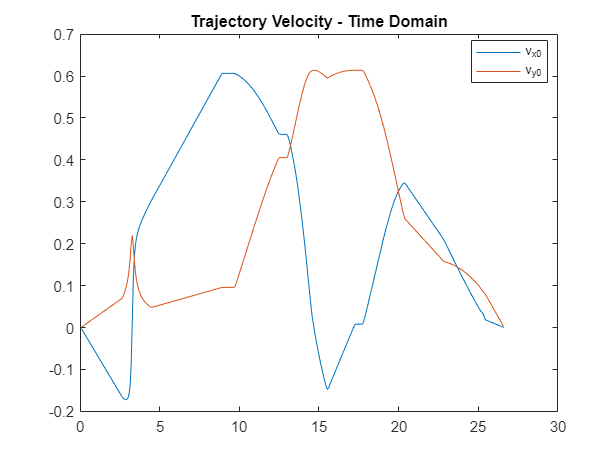


plot((1:length(traj)-1)'*1/15, diff(traj')*15)
title("Trajectory Velocity - Time Domain")
legend(["v_{x0}", "v_{y0}"], Location="best")

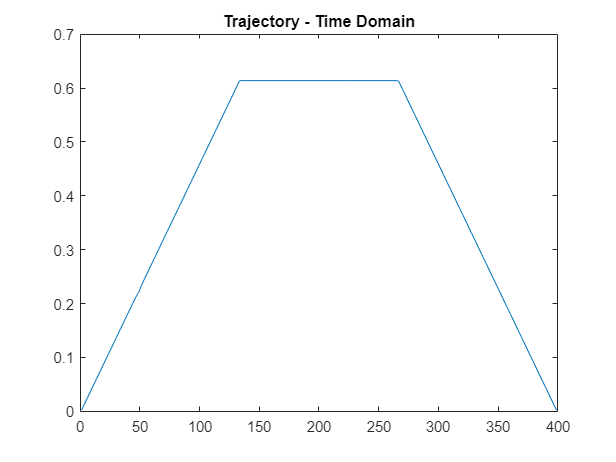



plot(vecnorm(diff(traj')')*15)
title("Trajectory - Time Domain")

% Convert offset (x,y) trajectory to (x,y,theta) COM trajectory

d_OS = 0.25;
N_steps = 400;
Ts = 1/15;


COM_traj = NaN([3 N_steps]);
COM_traj(:, 1) = [traj(:,1) - [d_OS; 0]; 0];

W_inv = diag([1 1.5 1].^-1);

for i = 2:N_steps
    v_os = (traj(:,i) - traj(:,i-1)) / Ts;
%     p_os_world = rot2(COM_traj(3,i-1)) * [d_OS; 0];
% 
%     J = [1 0 -p_os_world(2)
%          0 1  p_os_world(1)];
    J = [1 0 0
         0 1 d_OS];
    v_os_R = rot2(-COM_traj(3,i-1)) * v_os;
    %v_com_R = pinv(J)*v_os_R;
    v_com_R = W_inv*pinv(J*W_inv)*v_os_R;
    v_com = v_com_R;
    v_com(1:2) = rot2(COM_traj(3,i-1))*v_com_R(1:2);
    %v_com = pinv(J)*v_os;

    %v_com = W_inv_R*pinv(J*W_inv_R)*v_os;
    COM_traj(:,i) = COM_traj(:,i-1) + v_com*Ts;

end


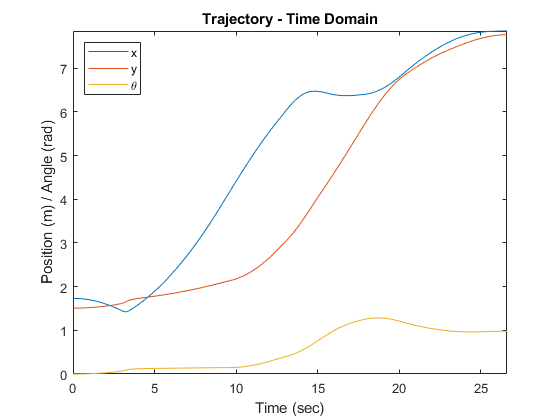

tt = Ts*(0:(N_steps-1));
plot(tt , COM_traj')
axis tight
title("Trajectory - Time Domain")
xlabel("Time (sec)")
ylabel("Position (m) / Angle (rad)")
legend(["x", "y","\theta"], Location="northwest")

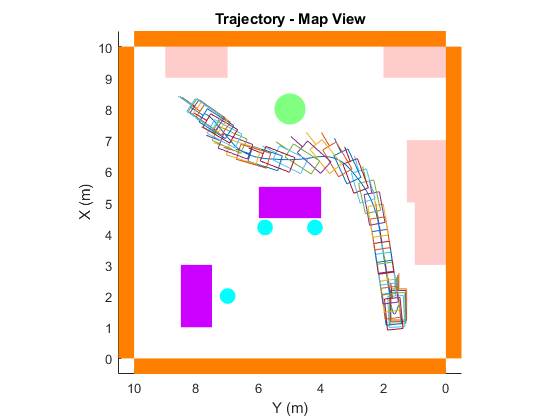



figure
hold on
roomshow(colobj);

plot(COM_traj(1,:),COM_traj(2,:));
view(-90,90);
axis image
title("Trajectory - Map View")

for i = 1:10:N_steps
    plot_cart(COM_traj(:,i))
end
hold off
xlabel("X (m)")
ylabel("Y (m)")

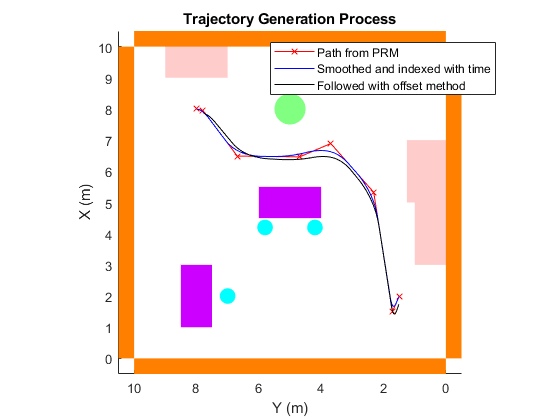

% Plot entire process


figure
hold on

plot(xy(:,1),xy(:,2), '-xr');
plot(traj(1,:),traj(2,:), 'b');
plot(COM_traj(1,:),COM_traj(2,:), 'k');
roomshow(colobj);
view(-90,90);
axis image
title("Trajectory Generation Process")

hold off
xlabel("X (m)")
ylabel("Y (m)")

legend(["Path from PRM", "Smoothed and indexed with time", "Followed with offset method"], Location="northeast")